# SPECTER Planar Dynamics Model

clear
clc
close all

## Initial Conditions

x0 = 0;
z0 = 0;
vx0 = 0;
vz0 = 0;
theta0 = 0;
omega0 = 0;

X0 = [x0;
    z0;
    vx0;
    vz0;
    theta0;
    omega0];

## Parameters

p.g = 9.80665;
p.l = 0.3;
p.I = 0.5;
p.delta = deg2rad(5);

% Mass
p.mWet = 10;
p.mDry = 9;

% Aerodynamics
p.Cd = 0.5;
p.Aref = 0.01;
p.rho = 1.225;

% Thrust
p.thrustTime = [0 0.1 0.3 1.0 1.8 2.0];
p.thrustData = [0 150 220 210 180 0];
p.tb = p.thrustTime(end);

## Dynamics Function Check

dX_test = SpecterDynamicsPlanar(0,X0,p)

dX_test =          0
         0
         0
   -9.8066
         0
         0


## Mass Model Verification

m0 = MassModelPlanar(0,p);
m05 = MassModelPlanar(0.5,p);
m10 = MassModelPlanar(1.0,p);
m15 = MassModelPlanar(1.5,p);
m20 = MassModelPlanar(2.0,p);
m25 = MassModelPlanar(2.5,p);

fprintf('\n--- MASS MODEL VERIFICATION ---\n\n');


--- MASS MODEL VERIFICATION ---




fprintf('m(0.0) = %.3f kg\n',m0);

m(0.0) = 10.000 kg


fprintf('m(0.5) = %.3f kg\n',m05);

m(0.5) = 9.750 kg


fprintf('m(1.0) = %.3f kg\n',m10);

m(1.0) = 9.500 kg


fprintf('m(1.5) = %.3f kg\n',m15);

m(1.5) = 9.250 kg


fprintf('m(2.0) = %.3f kg\n',m20);

m(2.0) = 9.000 kg


fprintf('m(2.5) = %.3f kg\n',m25);

m(2.5) = 9.000 kg


## Simulation

tfinal = 2;

dynamics = @(t,X) SpecterDynamicsPlanar(t,X,p);
solverOptions = odeset('RelTol',1e-9,'AbsTol',1e-11);
[t,X] = ode45(dynamics,[0,tfinal],X0,solverOptions);

## State Histories

x = X(:,1);
z = X(:,2);

vx = X(:,3);
vz = X(:,4);

theta = X(:,5);
omega = X(:,6);

## Mass History

mass = zeros(size(t));

for i = 1:length(t)
    mass(i) = MassModelPlanar(t(i),p);
end

## Aerodynamic History

V = zeros(size(t));
D = zeros(size(t));
Dx = zeros(size(t));
Dz = zeros(size(t));

for i = 1:length(t)

    V(i) = sqrt(vx(i)^2 + vz(i)^2);

    [Dx(i),Dz(i),D(i)] = DragModelPlanar(vx(i),vz(i),p);

end

## Drag Direction Verification

dragPower = Dx.*vx + Dz.*vz;

maxDragPower = max(dragPower);

fprintf('\n--- DRAG DIRECTION VERIFICATION ---\n\n');


--- DRAG DIRECTION VERIFICATION ---




fprintf('Maximum D dot V: %.12e W\n',maxDragPower);

Maximum D dot V: 0.000000000000e+00 W


## Initial Verification

fprintf('\n--- PLANAR MODEL INITIAL CHECK ---\n\n');


--- PLANAR MODEL INITIAL CHECK ---




fprintf('Final horizontal position: %.6f m\n',x(end));

Final horizontal position: 10.304703 m


fprintf('Final altitude: %.6f m\n',z(end));

Final altitude: -9.775892 m



fprintf('Final horizontal velocity: %.6f m/s\n',vx(end));

Final horizontal velocity: 6.014269 m/s


fprintf('Final vertical velocity: %.6f m/s\n',vz(end));

Final vertical velocity: -14.863402 m/s



fprintf('Final pitch angle: %.6f deg\n',rad2deg(theta(end)));

Final pitch angle: 1144.695814 deg


fprintf('Final pitch rate: %.6f deg/s\n',rad2deg(omega(end)));

Final pitch rate: 1105.595476 deg/s


## Thrust Model Verification

T0 = ThrustModelPlanar(0,p);
T01 = ThrustModelPlanar(0.1,p);
T03 = ThrustModelPlanar(0.3,p);
T10 = ThrustModelPlanar(1.0,p);
T18 = ThrustModelPlanar(1.8,p);
T20 = ThrustModelPlanar(2.0,p);
T25 = ThrustModelPlanar(2.5,p);

fprintf('\n--- THRUST MODEL VERIFICATION ---\n\n');


--- THRUST MODEL VERIFICATION ---




fprintf('T(0.0) = %.3f N\n',T0);

T(0.0) = 0.000 N


fprintf('T(0.1) = %.3f N\n',T01);

T(0.1) = 150.000 N


fprintf('T(0.3) = %.3f N\n',T03);

T(0.3) = 220.000 N


fprintf('T(1.0) = %.3f N\n',T10);

T(1.0) = 210.000 N


fprintf('T(1.8) = %.3f N\n',T18);

T(1.8) = 180.000 N


fprintf('T(2.0) = %.3f N\n',T20);

T(2.0) = 0.000 N


fprintf('T(2.5) = %.3f N\n',T25);

T(2.5) = 0.000 N


## Variable Thrust and Mass Dynamics Check

t_test = 0.3;

dX_test_03 = SpecterDynamicsPlanar(t_test,X0,p);

T_test = ThrustModelPlanar(t_test,p);
m_test = MassModelPlanar(t_test,p);

fprintf('\n--- DYNAMICS CHECK AT t = 0.3 s ---\n\n');


--- DYNAMICS CHECK AT t = 0.3 s ---




fprintf('Thrust:   %.6f N\n',T_test);

Thrust:   220.000000 N


fprintf('Mass:     %.6f kg\n',m_test);

Mass:     9.850000 kg



fprintf('xdot:     %.6f m/s\n',dX_test_03(1));

xdot:     0.000000 m/s


fprintf('zdot:     %.6f m/s\n',dX_test_03(2));

zdot:     0.000000 m/s


fprintf('ax:       %.6f m/s^2\n',dX_test_03(3));

ax:       1.946626 m/s^2


fprintf('az:       %.6f m/s^2\n',dX_test_03(4));

az:       12.443384 m/s^2


fprintf('thetadot: %.6f rad/s\n',dX_test_03(5));

thetadot: 0.000000 rad/s


fprintf('alpha:    %.6f rad/s^2\n',dX_test_03(6));

alpha:    11.504558 rad/s^2


## Drag Model Verification

vx_test = 3;
vz_test = 4;

[Dx_test,Dz_test,D_test] = DragModelPlanar(vx_test,vz_test,p);

fprintf('\n--- DRAG MODEL VERIFICATION ---\n\n');


--- DRAG MODEL VERIFICATION ---




fprintf('Velocity magnitude: %.6f m/s\n',sqrt(vx_test^2 + vz_test^2));

Velocity magnitude: 5.000000 m/s


fprintf('Drag magnitude: %.6f N\n',D_test);

Drag magnitude: 0.076563 N


fprintf('Drag x-component: %.6f N\n',Dx_test);

Drag x-component: -0.045937 N


fprintf('Drag z-component: %.6f N\n',Dz_test);

Drag z-component: -0.061250 N


## Drag Dynamics Verification

t_drag_test = 0.3;

X_drag_test = [0;
               0;
               3;
               4;
               0;
               0];

dX_drag_test = SpecterDynamicsPlanar(t_drag_test,X_drag_test,p);

fprintf('\n--- DRAG DYNAMICS VERIFICATION ---\n\n');


--- DRAG DYNAMICS VERIFICATION ---




fprintf('xdot:     %.6f m/s\n',dX_drag_test(1));

xdot:     3.000000 m/s


fprintf('zdot:     %.6f m/s\n',dX_drag_test(2));

zdot:     4.000000 m/s


fprintf('ax:       %.6f m/s^2\n',dX_drag_test(3));

ax:       1.941962 m/s^2


fprintf('az:       %.6f m/s^2\n',dX_drag_test(4));

az:       12.437166 m/s^2


fprintf('thetadot: %.6f rad/s\n',dX_drag_test(5));

thetadot: 0.000000 rad/s


fprintf('alpha:    %.6f rad/s^2\n',dX_drag_test(6));

alpha:    11.504558 rad/s^2


## Variable Thrust Rotational Verification

impulse = trapz(p.thrustTime,p.thrustData);

omega_exact_final = omega0 + ...
    (p.l*sin(p.delta)/p.I)*impulse;

omega_numerical_final = omega(end);

omega_final_error = abs(omega_numerical_final - omega_exact_final);

fprintf('\n--- VARIABLE THRUST ROTATIONAL VERIFICATION ---\n\n');


--- VARIABLE THRUST ROTATIONAL VERIFICATION ---




fprintf('Total impulse: %.6f N*s\n',impulse);

Total impulse: 369.000000 N*s


fprintf('Analytical final omega: %.12f rad/s\n',omega_exact_final);

Analytical final omega: 19.296281444332 rad/s


fprintf('ODE45 final omega: %.12f rad/s\n',omega_numerical_final);

ODE45 final omega: 19.296281243767 rad/s


fprintf('Final omega error: %.12e rad/s\n',omega_final_error);

Final omega error: 2.005640453717e-07 rad/s


## Plots

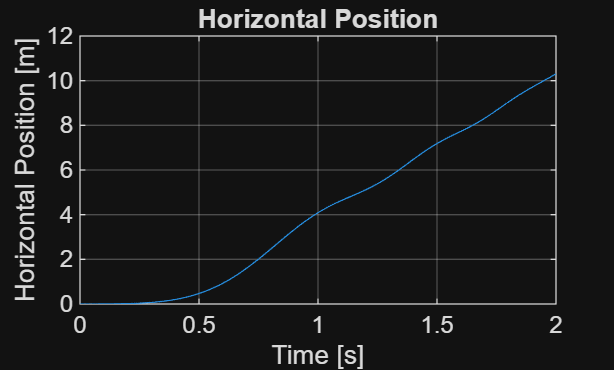

figure
plot(t,x)
xlabel('Time [s]')
ylabel('Horizontal Position [m]')
title('Horizontal Position')
grid on

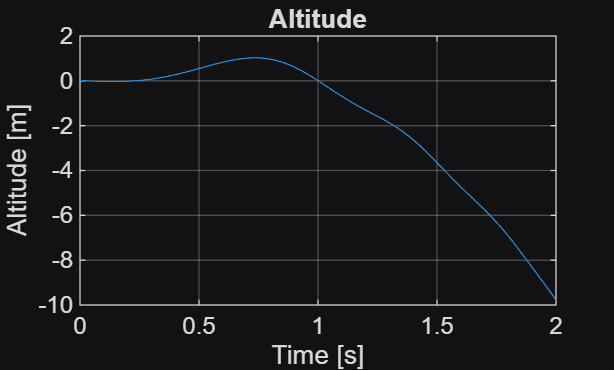


figure
plot(t,z)
xlabel('Time [s]')
ylabel('Altitude [m]')
title('Altitude')
grid on

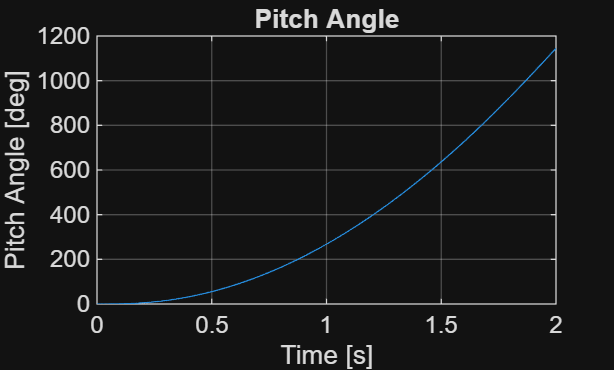


figure
plot(t,rad2deg(theta))
xlabel('Time [s]')
ylabel('Pitch Angle [deg]')
title('Pitch Angle')
grid on

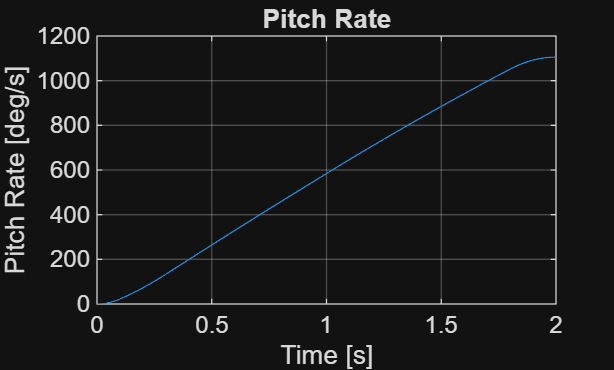


figure
plot(t,rad2deg(omega))
xlabel('Time [s]')
ylabel('Pitch Rate [deg/s]')
title('Pitch Rate')
grid on

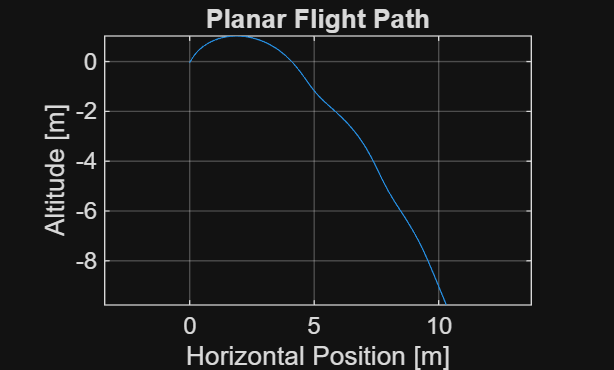


figure
plot(x,z)
xlabel('Horizontal Position [m]')
ylabel('Altitude [m]')
title('Planar Flight Path')
grid on
axis equal

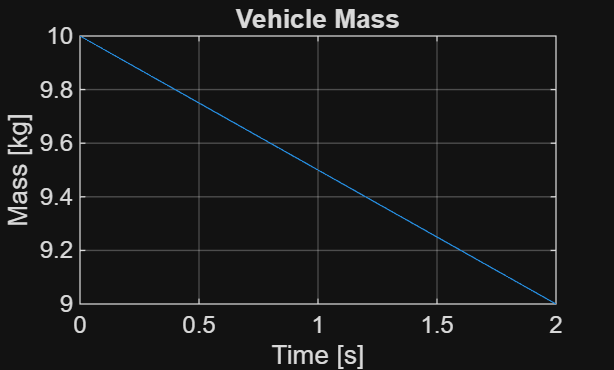


figure
plot(t,mass)
xlabel('Time [s]')
ylabel('Mass [kg]')
title('Vehicle Mass')
grid on

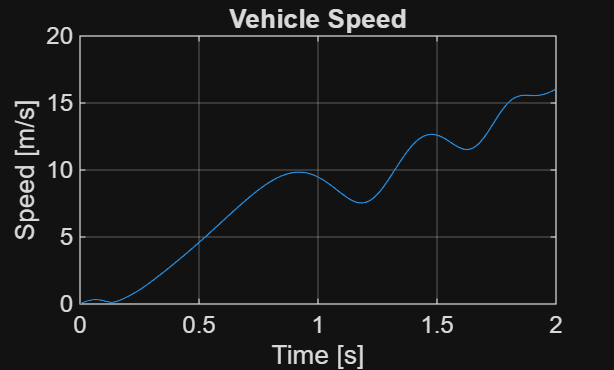


figure
plot(t,V)
xlabel('Time [s]')
ylabel('Speed [m/s]')
title('Vehicle Speed')
grid on

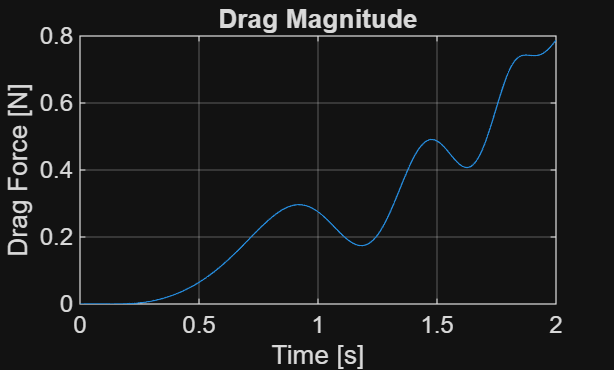


figure
plot(t,D)
xlabel('Time [s]')
ylabel('Drag Force [N]')
title('Drag Magnitude')
grid on